directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\1_Runde_Schilder\Geschwindigkeitsbegrenzungen\Geschwindigkeitsbegrenzung 30\Ackerstraße";
cd(directory);      % Arbeitsverzeichnis setzen


I = imread("Geschwindigkeitsbegrenzung_30-2025-06-06__14.jpg");

%imshow(I);

grayImage = rgb2gray(I);
%imshowpair(I, grayImage, method = "montage");
% imwrite(grayImage, "test.jpg");
grayImagefilter = imgaussfilt(grayImage, 2); % Rauschentfernung 
edges = edge(grayImage, 'Canny'); % Verwendung des Canny-Algorithmus
%imshowpair(grayImagefilter, edges, method = "montage");
%imshowpair(grayImagefilter, grayImage, method = "montage");
% imwrite(grayImagefilter, "test.jpg");
binaryImg = imbinarize(grayImage);
%imshowpair(binaryImg, grayImage, method = "montage");
% imwrite(binaryImg, "test2.jpg");


Test Kreiserkennung

imshow(I);
[centers, radii] = imfindcircles(I, [15, 50], 'Sensitivity', 0.90)

centers = 1.0e+03 *

    1.1539    0.3987


radii = 41.4569

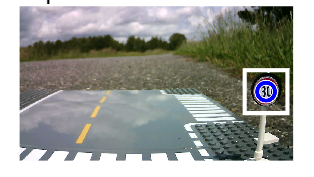

directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bildausschnitte"

viscircles(centers, radii,'EdgeColor','b');
numCircles = size(centers, 1);

for a = 1:numCircles
    x = centers(a, 1);      % x-Koordinate des Mittelpunkts
    y = centers(a, 2);      % y-Koordinate des Mittelpunkts
    r = radii(a);           % Radius des Kreises
    roi = [x-100, y-100, 200, 200];
    rectangle('Position', roi, 'EdgeColor', 'w', 'LineWidth', 2);
    title(' Geplanter Bildausschnitt in Rot');
    directory= "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bildausschnitte"
    cd(directory);
    croppedImg = imcrop(I, roi);
    imwrite(croppedImg, 'ausgeschnitten.jpg');
end